# ばね・おもり・ダンパ系のシミュレーション(制御なし)

このファイルではばね・おもり・ダンパ系に対し，制御を加えないシミュレーションを実行します．

### 系の設定

変数を消去し，パラメータを設定します．

微分方程式は以下です．


$$M\ddot{{x}}=-D\dot{x}-Kx+u$$


clear
clc
close all

parameterSetup

[質量　ダンパ定数　ばね定数]

[M D K]

ans =      1     1     1


状態空間表現


$$\dot{x}=Ax+bu, y=cx$$


sys=ss(A,b,c,d)

sys =
 
  A = 
       x1  x2
   x1   0   1
   x2  -1  -1
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
連続時間状態空間モデル。
モデル プロパティ


評価関数とその重み


$$J=\int_0^\infty\left(x^\top Q x+u^\top R u \right)dt$$


Q

Q =      1     0
     0     1


R

R = 1

初期条件

x0=[1;0]

x0 =      1
     0


初期条件からの応答を計算して図示

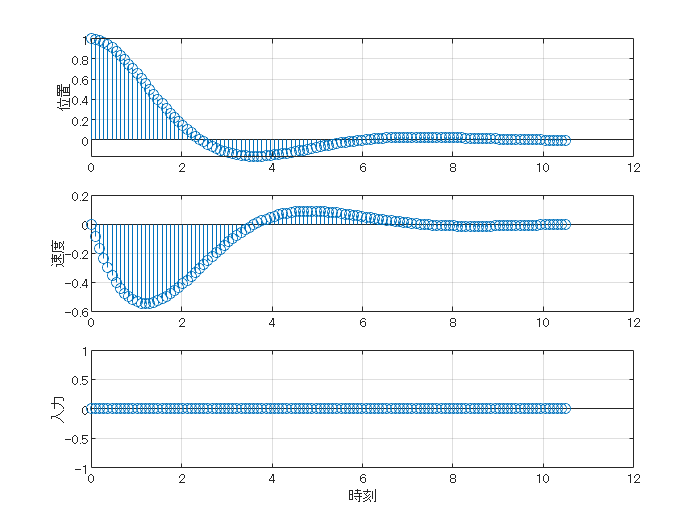

[y,tOut,x]=initial(sys,x0);
u=zeros(size(tOut));
figure
tiledlayout(3,1)
nexttile
h1_x=stem(tOut, y,'-');
grid on;
ylabel('位置')
nexttile
h1_v=stem(tOut, x(:,2),'-');
grid on
ylabel('速度')
nexttile
h1_u=stem(tOut, u,'-');
grid on;
ylabel('入力')
xlabel('時刻')

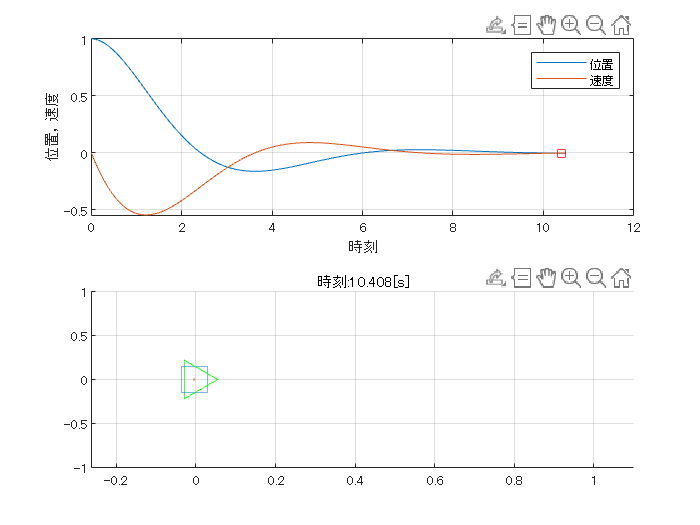

figure;
tiledlayout(2,1);
nexttile
h2=plot(tOut,x);
hold on;
h2_x=plot(0,x(1,1),'bs');
h2_v=plot(0,x(1,2),'rs');
grid on;
xlabel('時刻');
ylabel('位置，速度');
legend(h2,{'位置','速度'})
nexttile
hold on;
h1=plot(x0(1),0,'s','MarkerSize',20);
h1_v=quiver(x0(1),0,x(1,2),0,'off');
h1_v.ShowArrowHead="off";
h1_v.LineWidth=1.5;
% set(h1_v,'scale','off')
grid on;
plot(0,0,'g>','MarkerSize',20)
xlim([min(y)-0.1 max(y)+0.1]);
grid on
for n1=1:size(y,1)-1
    set(h1,XData=y(n1));
    set(h2_x,XData=tOut(n1), YData=y(n1));
    set(h2_v,XData=tOut(n1), YData=x(n1,2));
    set(h1_v,"XData",y(n1),"UData",x(n1,2));
    title(['時刻:' num2str(tOut(n1),'%1.3f') '[s]'])
    if Opt.drawAnimation
        pause(0.05);
    end
end

評価(値が小さく0に近いほど良い)

J=sum(Q(1,1)*x(1:end-1,1).^2.*diff(tOut)) ...
    +sum(Q(2,2)*x(1:end-1,2).^2.*diff(tOut)) ...
    +sum(R*u(1:end-1,1).^2.*diff(tOut))

J = 1.5460